# Generating SVDPI Component for MATLAB Code with MEX Function Calls

- MATLAB users might want to execute external C function in MATLAB by generating a MEX function. But for code generation, the user still wants the external C code to be part of the generated DPI-C code base. 

- Here is an example C code, which is used in MATLAB as mex but also can be used for DPIC model generation. 

type("C_SRC\my_mean.c","C_SRC\my_mean.h");

/* Include files */
#include "my_mean.h"

/* This is a custom mean function that returns output by value */

/* Function Definitions */
double my_mean(const double x[17])
{
  double y;
  int k;
  y = x[0];
  for(k = 0; k < 16; k++) {
    y += x[k + 1];
  }
  y /= 17.0;
  return y;
}

/* Include files */
#include <math.h>

/* Function Declarations */
extern double my_mean(const double x[17]);


### **Step1: Create a MATLAB function to call external C code using coder.eval**

- Use `coder.eval` to call your external C code. For example- if we want to use `my_mean.c` as external C function, we can use `code.ceval` to call this function. 

type('call_moving_avg')

### **Step 2: Create a MEX file for this function**

codegen -config:mex call_moving_avg -args {zeros(1,1024)}

function y = call_moving_avg(x) %#codegen

SRC_PATH = '$(START_DIR)\C_SRC'; % Path relative to codegen/mex/call_moving_avg folder
%External Source Code and Header
coder.updateBuildInfo('addIncludePaths',SRC_PATH);
coder.updateBuildInfo('addSourcePaths',SRC_PATH);
coder.cinclude('my_mean.h');
coder.updateBuildInfo('addSourceFiles','my_mean.c');

% Preallocation

y = zeros(1,length(x)-16);
%Moving average
for i = 1:length(x) -16
 x1 = x(i:i+16);
 y(i) = coder.ceval('my_mean',coder.ref(x1));

end


### **Step 3: Create a wrapper MATLAB function that uses coder.target to determine if it is executing in MATLAB or in code generation. In MATLAB mex version of the function is used. **

type('wrapper_moving_avg')

**Testbench function which calls wrapper_moving_avg**

tb_moving_avg;

Code generation successful.



### **Step 4: Generating DPI-C code along with Testbench**

 SV DPIC model is generated in the codegen / dll / wrapperMovingAvg folder.

function y  = wrapper_moving_avg(x)

if coder.target('MATLAB')
  y = call_moving_avg_mex(x);
  fprintf('Function Running in MATLAB \n');
else
  disp(coder.target());  
  y = call_moving_avg(x);
  fprintf('Function Running in generated code \n');
end
end


Function Running in MATLAB 


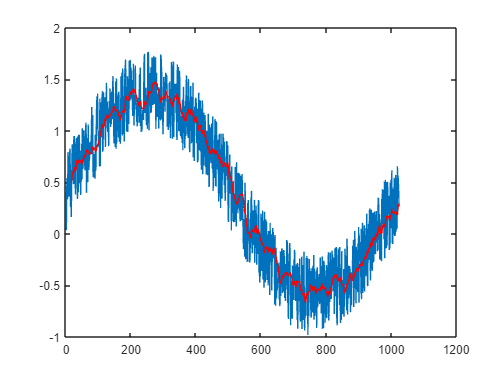

### Generating DPI-C Wrapper wrapperMovingAvg_dpi.c
### Generating DPI-C Wrapper header file wrapperMovingAvg_dpi.h
### Generating SystemVerilog module package wrapperMovingAvg_dpi_pkg.sv
### Generating SystemVerilog module wrapperMovingAvg_dpi.sv
### Generating mak

gen_dpi

Copyright 2024 The MathWorks, Inc.